# P1. Dinámica Longitudinal del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 18 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta primera práctica definiremos las propiedades, los parámetros de diseño de nuestro monoplaza de competición FSDriverless y diseñaremos el primer modelo dinámica longitudinal. 

Para completar esta práctica se necesita conocer la ecuación fundamental de movimiento longitudinal de un vehículo desarrollada en el Bloque 2. 

Al terminar esta práctica deberás ser capaz de:

- Escribir y simular la ecuación de movimiento longitudinal de un vehículo.

- Cerrar un lazo sencillo de control de velocidad. 

- Reconocer la estructura de simulación que reutilizaremos y ampliaremos en las siguientes prácticas.

🚧 **Importante**: *este es el primer bloque de tu proyecto individual. El archivo que completes hoy se convertirá en la base longitudinal del simulador del sistema de control de tu monoplaza que utilizarás durante todo el curso. Guárdalo. *

#### Qué vas a implementar

A) La aceleración longitudinal (función `pasoLongitudinal`)

B) La ley de control PI saturada (función `controlLongitudinal`)

### Parametros del vehículo

💡 **Tip**: *Vamos a utilizar un *`struct`* (o estructura). En Matlab las estructuras son un tipo de datos que agrupa información relacionada mediante contenedores llamados campos. Cada campo puede almacenar cualquier tipo de dato (números, texto, vectores, u otras matrices).* 

p = struct();
p.m = 230; % masas e kg
p.g = 9.81; % fuerza de la gravedad
p.rho = 1.225; % densidad del aire
p.Cd = 1.0; % aerodinámica
p.Af = 1.1; % área frontal
p.fr = 0.022;
p.Fx_trac_max = 2500; % fuerza motriz máxima
p.Fx_fren_max = 5000; % fuerza de frenado máxima
p.theta = 0; %rad

🧠 **Recordatorio**: la fuerza motriz máxima viene definida por el límite de adherencia del neumático y el límite de potencia/par del tren motriz. En el caso de la fuerza de frenado máxima, esta suele estar igualmente limitada por la adherencia pero con la ventaja del frenado de las cuatro ruedas (frente a un tracción trasera), lo que permite aprovechar el 100% de la masa del vehículo y la carga aerodinámica disponible.

### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal. Más adelante esta sección incluirá el modelo de nuestro vehículo al completo. 

Dada la posición del vehículo y la fuerza tractiva aplicada, deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

% Integración de la dinámica longitudinal
z0 = [0;0]; % vector de estados del vehículo [x,v_x]

function z_next = pasoLongitudinal(z, u, p, dt)
    Fx=u;
    v_x=z(2);

    %resistencias
    Ra = 0.5*p.rho*p.Cd*p.Af*v_x^2; % resistencia aerodinámica
    Rr = p.fr*p.m*p.g*cos(p.theta); % rodadura
    Rg = p.m*p.g*sin(p.theta); % gravitatoria

    %aceleración
    ax = (Fx - Ra - sign(v_x)*Rr - Rg)/p.m;
   
    %velocidad
    vx_next = max(v_x + ax*dt,0); %velocidad en el siguiente instante de tiempo
    x_next = z(1)+v_x*dt;
    z_next = z;
    z_next(1) = x_next;
    z_next(2) = vx_next;
end

### Controlador velocidad 

Vamos a definir aquí nuestro controlador de velocidad en base al siguiente diagrama:

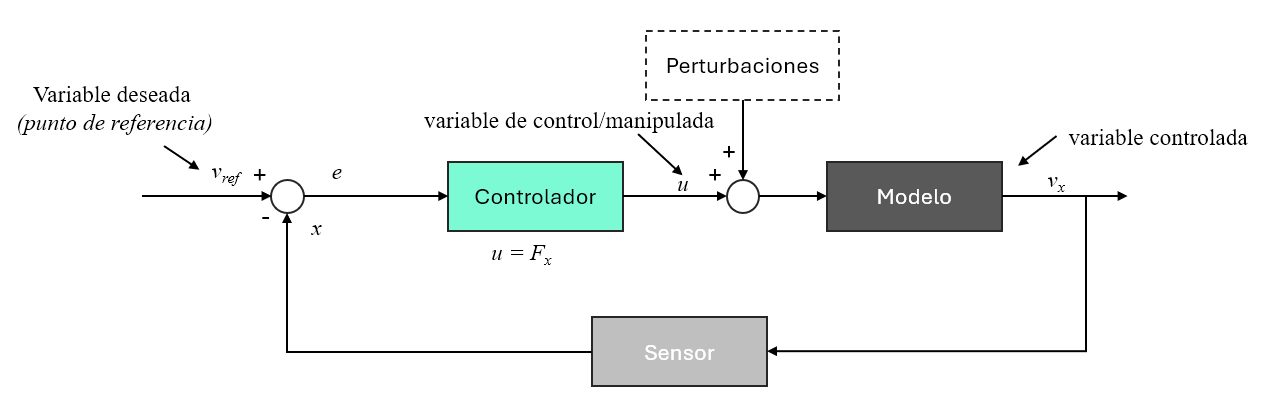

#### Recordatorio sobre controladores PI

Vamos a implementar un controlador PI de velocidad. Queremos que $v_x$ siga una referencia $v_{ref}$. El error, por tanto, vendrá definido por 


$$e = v_{ref} - v_x$$


y pedimos una fuerza de tracción proporcional a este error mas un termino integral que elimina el error en regimen permanente:


$$F_x = K_p \cdot e + K_i \int{e \cdot dt}$$


La fuerza real que se puede ejercer estará limitada por la adherencia y la capacidad de nuestro motor. $F_x
$ saturará entre máximo de frenado y el máximo de aceleración. 

**🧠Recordatorio**: *La saturación de un controlador ocurre cuando la señal de salida que calcula el controlador supera los límites físicos, eléctricos o de software del actuador que debe ejecutar la orden.*

💡*¿Por qué fuerza de tracción como variable de control? *Esta es una decisión que facilita la integración con la ecuación que gobierna el movimiento longitudinal. Es una manera de abstraer todo el tren de potencia (real) colapsándolo en una sola variable. En la realidad necesitaríamos modelar todo el tren de potencia (pedal del acelerador → par motor → fuerza tractiva) utilizando los mapas proprios del motor (no lineales para motores de combustion interna). 

% Controlador PI de velocidad
ctrl.v_cru = 25; % velocidad de crucero objetivo [m/s]
ctrl.x_fren = 78; % distancia a la que se ordena frenar [m]
ctrl.Kp = 800; % ganancia proporcional
ctrl.Ki = 200; % ganancia integral

function [Fx,e_int] = controlLongitudinal(v_ref, v_x, e_int, dt, ctrl, p)
    e = v_ref - v_x;
    %integral del error
    e_int = e_int + e*dt;
    Fx = ctrl.Kp*e+ctrl.Ki*e_int;

    % límite de saturación de mi conrtolador
    Fx = min(max(Fx,  -p.Fx_fren_max), p.Fx_trac_max);
end

### Geometría del circuito de pruebas

Vamos a simular una aceleración máxima durante 75 m seguida de una frenada en caja que deberá completarse en menos de 25 m (límite máximo de frenada a los 100 m). 

p.x_meta = 75;     % línea de cronometraje [m]
p.x_box  = 100;    % final de la caja de frenada [m]

%% SIMULADOR DE PRUEBA ACELERACIÓN Y FRENADA [NO MODIFICAR]
function [hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax)
    N = round(Tmax/dt);
    z = z0;
    hist.t  = zeros(1,N); hist.X  = zeros(1,N); hist.vx = zeros(1,N);
    hist.Fx = zeros(1,N); hist.vr = zeros(1,N);
    e_int = 0;  cruzada = false;  t_evento = NaN;  k_fin = N;
    for k = 1:N
        t = (k-1)*dt;
        if z(1) < ctrl.x_fren,  v_ref = ctrl.v_cru;  else,  v_ref = 0;  end
        [Fx, e_int] = controlLongitudinal(v_ref, z(2), e_int, dt, ctrl, p);
        z = pasoLongitudinal(z, Fx, p, dt);   % mando u = [Fx; delta]; delta = 0 en L1
        hist.t(k)=t; hist.X(k)=z(1); hist.vx(k)=z(2); hist.Fx(k)=Fx; hist.vr(k)=v_ref;
        if ~cruzada && z(1) >= p.x_meta,  cruzada = true;  t_evento = t;  end
        if cruzada && z(2) <= 0.05,  k_fin = k;  break;  end
    end
    f = 1:k_fin;
    hist.t=hist.t(f); hist.x=hist.X(f); hist.vx=hist.vx(f);
    hist.Fx=hist.Fx(f); hist.vr=hist.vr(f);
end

### Simulación

dt   = 0.005;
Tmax = 20; 

[hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax);

### Resultados 

**Qué esperar**: Deberíamos observar como el monoplaza acelera desde parado hasta la velocidad de crucero establecida (90 km/h) y la mantiene hasa cruzar la linea de 75m donde hemos establecido el comienzo de la frenada. Tras cruzar esta línea frena y se detiene dentro de la caja (antes de 100 m aprox).

fprintf('E1 — cruza %.0f m en  t = %.2f s\n', p.x_meta, t_evento);

E1 — cruza 75 m en  t = 3.96 s


fprintf('     se detiene en  X = %.1f m  (t = %.2f s)\n', hist.x(end), hist.t(end));

     se detiene en  X = 101.1 m  (t = 14.70 s)


fprintf('     v_max = %.1f m/s = %.0f km/h\n', max(hist.vx), max(hist.vx)*3.6);

     v_max = 30.7 m/s = 111 km/h


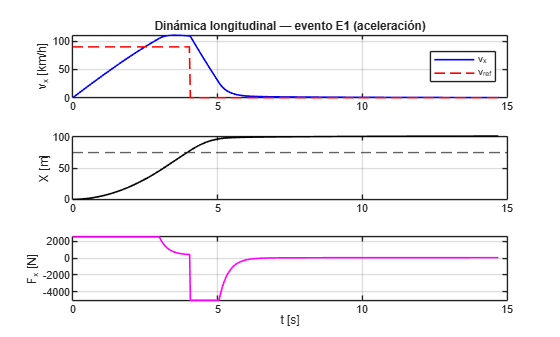

figure('Name','L1 · E1 — resultados','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vr*3.6,'r--','LineWidth',1.2);
  ylabel('v_x [km/h]'); grid on; legend('v_x','v_{ref}','Location','best');
  title('Dinámica longitudinal — evento E1 (aceleración)');
subplot(3,1,2);
  plot(hist.t, hist.x,'k','LineWidth',1.2); yline(p.x_meta,'--');
  ylabel('X [m]'); grid on;
subplot(3,1,3);
  plot(hist.t, hist.Fx,'m','LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;